clear all;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


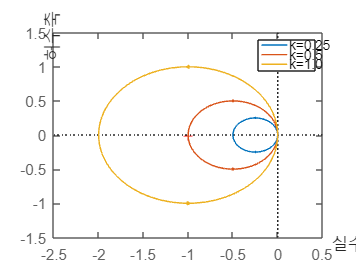

G1 = 0.25/(s-0.5);
G2 = 0.5/(s-0.5);
G3 = 1.0/(s-0.5);
nyquist(G1,G2,G3)
legend('k=0.25','k=0.5','k=1.0')
axis([-2.5 0.5 -1.5 1.5])

G = 1/(s^2 + 0.5*s + 1)

G =
 
         1
  ---------------
  s^2 + 0.5 s + 1
 
연속시간 전달 함수입니다.
모델 속성


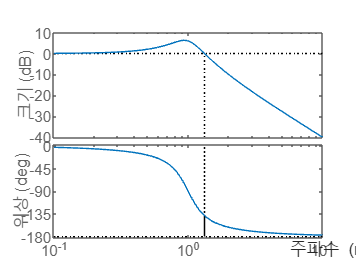

margin(G)

bandwidth(G)

ans = 1.4839

bandwidth(G,-10)

ans = 2.0000

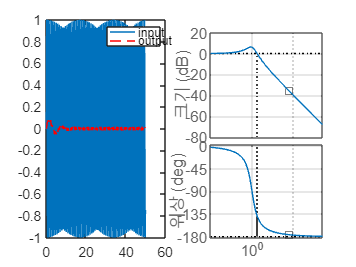

w =7.9;
t = [0:0.1:50];
u = sin(w*t);
[y,t,x] = lsim(G,u,t);
f1 = figure;
subplot(1,2,1)
plot(t,u,t,y,'r--');
legend('input','output');

subplot(1,2,2)
bode(G,w,'ks')
hold on
margin(G,{0.1,50});
hold off
grid;